## **IMPLEMENTAZIONE**

### **Inizializzazione**

clc
clear
close all

### **Dati del problema in esame:**

%Masse
m1 = 5.0;
m2 = 2.0; 
m3 = 1.0; 
m4 = 4.0; 

%Smorzatori
b1 = 0.47;
b2 = 0.35;
b3 = 0.41;
b4 = 0.23;

%Costanti Elastiche
k1 = 4.3;
k2 = 5.2; 
k3 = 2.5; 
k4 = 5.1; 
k4a = 4.9;
k4b = 2.3;
k4c = 6.2;
keq = (k4a*(k4b+k4c))/(k4a+k4b+k4c);

%Modello Fisico-Matematico
A = [0 0 0 0 1 0 0 0;
    0 0 0 0 0 1 0 0;
    0 0 0 0 0 0 1 0;
    0 0 0 0 0 0 0 1;
    -(keq+k1)/m1 k1/m1 0 keq/m1 -b1/m1 b1/m1 0 0;
    k1/m2 -(k1+k2)/m2 k2/m2 0 b1/m2 -(b1+b2)/m2 b2/m2 0;
    0 k2/m3 -(k3+k2)/m3 k3/m3 0 b2/m3 -(b2+b3)/m3 b3/m3;
    keq/m4 0 k3/m4 -(k4+keq+k3)/m4 0 0 b3/m4 -(b3+b4)/m4];

B = [zeros(5,2);
    1/m2 0;
    0 0;
    0 1/m3];

C = [1 0 0 0 0 0 0 0; 0 0 1 0 0 0 0 0]; 

D = zeros(2,2);

%Definizione del sistema
sys = ss(A,B,C,D)


sys =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1       0       0       0       0       1       0       0       0
   x2       0       0       0       0       0       1       0       0
   x3       0       0       0       0       0       0       1       0
   x4       0       0       0       0       0       0       0       1
   x5  -1.482    0.86       0  0.6216  -0.094   0.094       0       0
   x6    2.15   -4.75     2.6       0   0.235   -0.41   0.175       0
   x7       0     5.2    -7.7     2.5       0    0.35   -0.76    0.41
   x8  0.7771       0   0.625  -2.677       0       0  0.1025   -0.16
 
  B = 
        u1   u2
   x1    0    0
   x2    0    0
   x3    0    0
   x4    0    0
   x5    0    0
   x6  0.5    0
   x7    0    0
   x8    0    1
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   0   1   0   0   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-spa

### Analisi preliminare:

%Verifica delle caratteristihe del sistema a ciclo aperto
eig(A)

ans =   -0.4604 + 3.1910i
  -0.4604 - 3.1910i
  -0.0067 + 0.5295i
  -0.0067 - 0.5295i
  -0.1929 + 1.7758i
  -0.1929 - 1.7758i
  -0.0520 + 1.6518i
  -0.0520 - 1.6518i


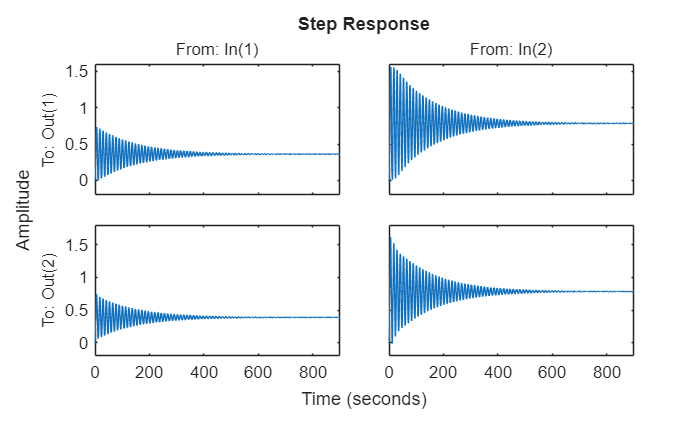

step(sys); 

Mc = ctrb(A,B);
rank(Mc)

ans = 8

Mo = obsv(A,C);
rank(Mo)

ans = 8

## **CONTROLLO CON ALLOCAZIONE DEGLI AUTOVALORI**

A_aug = [A zeros(8,2); -C zeros(2,2)];
B_aug = [B; zeros(2,2)];
C_aug = [C zeros(2,2)];
D_aug = D;
sys_aug = ss(A_aug,B_aug,C_aug,D_aug)


sys_aug =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10
   x1        0       0       0       0       1       0       0       0       0       0
   x2        0       0       0       0       0       1       0       0       0       0
   x3        0       0       0       0       0       0       1       0       0       0
   x4        0       0       0       0       0       0       0       1       0       0
   x5   -1.482    0.86       0  0.6216  -0.094   0.094       0       0       0       0
   x6     2.15   -4.75     2.6       0   0.235   -0.41   0.175       0       0       0
   x7        0     5.2    -7.7     2.5       0    0.35   -0.76    0.41       0       0
   x8   0.7771       0   0.625  -2.677       0       0  0.1025   -0.16       0       0
   x9       -1       0       0       0       0       0       0       0       0       0
   x10       0       0      -1       0       0       0       0       0       0       0
 
  B = 
         u1   

rank(ctrb(A_aug,B_aug))

ans = 10

PO = 20;
Ta_1 = 15;
%Ta_1 = 5;
%zita = abs(log(PO/100))/sqrt(pi^2+log(PO/100)^2);
zita = 0.5;
%w_n = 4.6/(zita*Ta_1);
w_n = 0.7;
%w_n = 1.9
Re = -(zita*w_n);
Imm = w_n*sqrt(1-zita^2);

lam1 = Re + 1j*Imm;
lam2 = lam1';

%si pongono gli altri poli molto più distanti da quelli dominanti (almeno
%una decade dopo)
lam3 = 10*real(lam1);
lamba_d = [lam1; lam2; lam3; lam3-1; lam3-2; lam3-3; lam3-4; lam3-5; lam3-6; lam3-7];
K = place(A_aug, B_aug, lamba_d);
Ki = K(:,9:10)

Ki = 1.0e+03 *

    3.0695   -2.8540
   -0.1580   -0.9091


Kr = K(:,1:8)

Kr = 1.0e+03 *

   -0.5637    0.4506    0.2737   -0.2629   -2.7892    0.0508    0.7152    0.0023
    0.2831    0.0543    1.3414    0.3503    2.1199    0.0096   -0.0179    0.0299


%%sys_star = ss(A+B*K, B, C, D);
%Non è possibile applicare il metodo ITAE essendo il sistema dell'ordine 8
%autovalori_star = sort(eig(sys_star))
%step(sys_star);
%prec = pinv(dcgain(ss(A+B*K,B,C+D*K,D)));
%sys_prec = ss(A+B*K,B*prec,C,D*prec);
%%H=dcgain(ss(A+B*K,B,C+D*K,D));
%G=pinv(H); 
%Ki=K(:,11:12);
%Kr=K(:,1:10);
%K

### Progetto Osservatore

lambda_obs = [-2; -3; -4; -5; -9; -10; -11; -12];
L = place(A',C',lambda_obs)';
%Costruiamo le matrici dell'osservatore
A_obs = (A-L*C); 
B_obs = [B-L*D L]; 
C_obs = eye(8);
D_obs = zeros(8,4);


### Schema Simulink

out1 = sim("Assegnamento_Autovalori.slx");

#### Risultati:

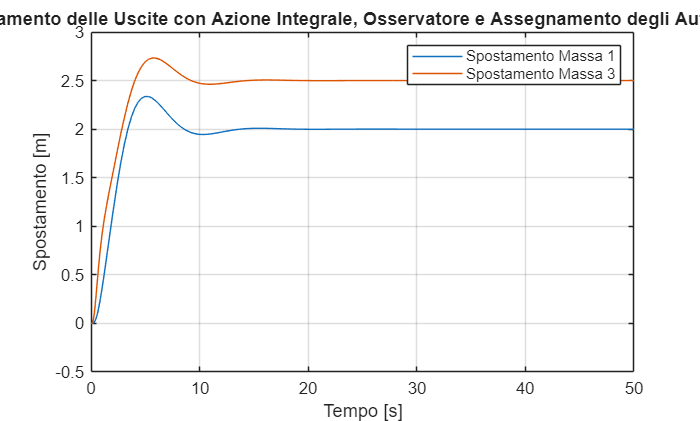

plot(out1.output.time, out1.output.signals.values)
title("Andamento delle Uscite con Azione Integrale, Osservatore e Assegnamento degli Autovalori");
xlabel("Tempo [s]");
ylabel("Spostamento [m]");
legend("Spostamento Massa 1","Spostamento Massa 3");
grid;

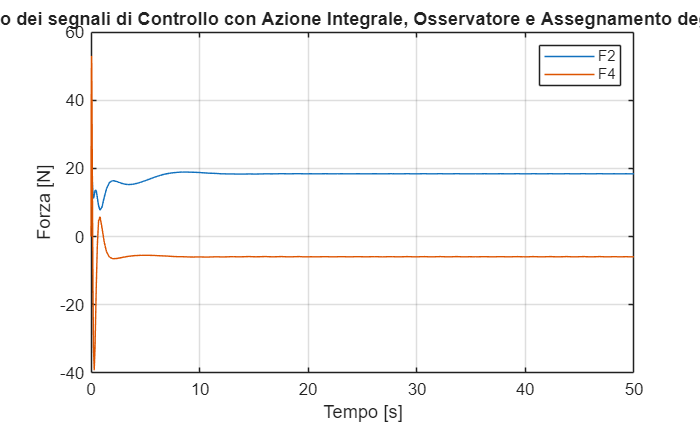

plot(out1.control.time, out1.control.signals.values)
title("Andamento dei segnali di Controllo con Azione Integrale, Osservatore e Assegnamento degli Autovalori");
xlabel("Tempo [s]");
ylabel("Forza [N]");
legend("F2","F4");
grid;

## **CONTROLLO LQ (LINEARE QUADRATICO)**

%Qp = 1;
Qp = 100;
Q = Qp*(C_aug')*C_aug;
Q = Q+blkdiag(zeros(8),eye(2,2));
%Q(10,10) = 1;
%Q(9,9) = 1;
Q(10,10) = 20;
Q(9,9) = 20;
Q

Q =    100     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    20     0
     0     0     0     0     0     0     0     0     0    20


%peso1=10000; peso2=10000; peso3=1;
%Q=peso1*(C_aug'*C_aug)+peso2*blkdiag(zeros(8),eye(2,2));
%R=peso3*eye(2,2);
%[K_lqr,P_lqr,e_lqr]=lqr(sys_aug,Q,R);
Rp = 0.1;
R = Rp*eye(2,2)

R =     0.1000         0
         0    0.1000


[F,P,CLP] = lqr(sys_aug,Q,R);
Fi = F(:,9:10);
Fr = F(:,1:8);
eig(P)

ans =     0.1068
    0.2179
    0.4965
    0.5782
   15.0615
   24.6966
   43.4197
   64.3153
  102.6076
  241.9245


CLP

CLP =   -0.2098 + 0.0000i
  -0.4468 + 0.0000i
  -0.4745 + 2.1289i
  -0.4745 - 2.1289i
  -0.6978 + 1.2730i
  -0.6978 - 1.2730i
  -1.0163 + 3.8518i
  -1.0163 - 3.8518i
  -2.2682 + 1.4545i
  -2.2682 - 1.4545i


### Schema Simulink

out2 = sim("Controllo_Ottimo_LQ")

out2 =   Simulink.SimulationOutput:

              controlLQ: [1x1 struct] 
               outputLQ: [1x1 struct] 
                   tout: [188x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Risultati:

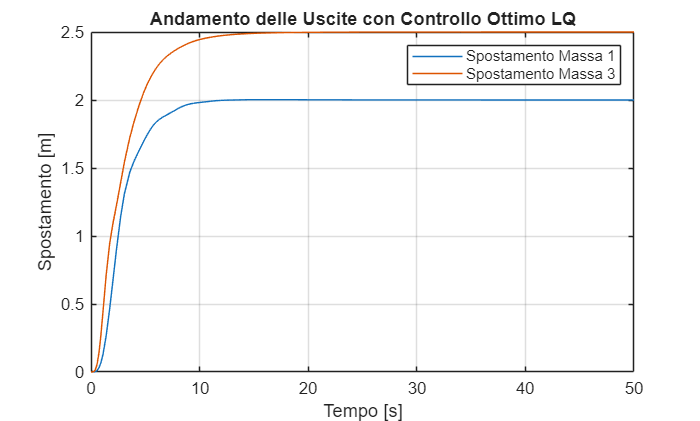

plot(out2.outputLQ.time, out2.outputLQ.signals.values)
title("Andamento delle Uscite con Controllo Ottimo LQ");
xlabel("Tempo [s]");
ylabel("Spostamento [m]");
legend("Spostamento Massa 1","Spostamento Massa 3");
grid;

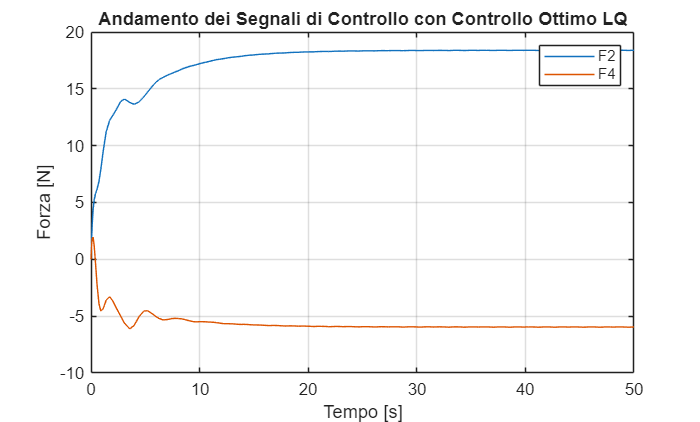

plot(out2.controlLQ.time, out2.controlLQ.signals.values)
title("Andamento dei Segnali di Controllo con Controllo Ottimo LQ");
xlabel("Tempo [s]");
ylabel("Forza [N]");
legend("F2","F4");
grid;

## **CONTROLLO LQG**

Bound=100; 
Tc=1/(2*Bound);
NoisePower=1e-5/2;
%sigma2=NoisePower*Tc;
%per il rumore in ingresso si è scelto di assegnare direttamente la
%covarianza

Qnoise = 1e-6*10;
Rnoise = 1e-8*2.5;
Rt = eye(2)*Rnoise;      %covarianza disturbo in uscita
Qt = eye(8)*Qnoise;    %covarianza disturbo in ingresso

Il filtro di kalman verrà risolto come problema LQR sul sistema duale:

[L_k,P_Kal,p_Kal] = lqr(A',C',Qt,Rt); 
L_k = L_k'; 
L_k

L_k =    20.9586    0.4987
    4.2398   14.4746
    0.4987   22.2541
    2.3855   12.4868
   19.7565   10.8587
    4.9336   -7.3704
   10.6895   47.7464
   -8.9518  -16.1349


%Filtro di Kalman
A_Kal = (A-L_k*C); 
B_Kal = [B-L_k*D L_k]; 
C_Kal = eye(8); 
D_Kal = zeros(8,4); 

### Schema Simulink

out3 = sim("Controllo_Ottimo_LQG")

out3 =   Simulink.SimulationOutput:

                     Du: [1x1 struct] 
                     Dy: [1x1 struct] 
         controlLQG_KAL: [1x1 struct] 
          outputLQG_KAL: [1x1 struct] 
        outputLQG_KAL_N: [1x1 struct] 
                   tout: [10005x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Risultati:

#### **Risultati con Filtro di Kalman**

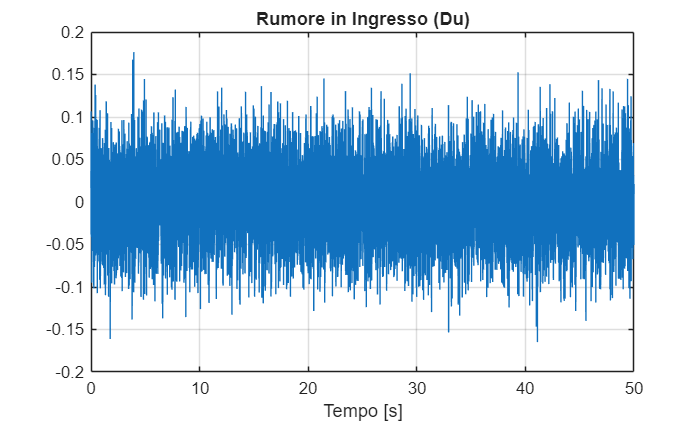

plot(out3.Du.time, out3.Du.signals.values)
title("Rumore in Ingresso (Du)");
xlabel("Tempo [s]");
grid;

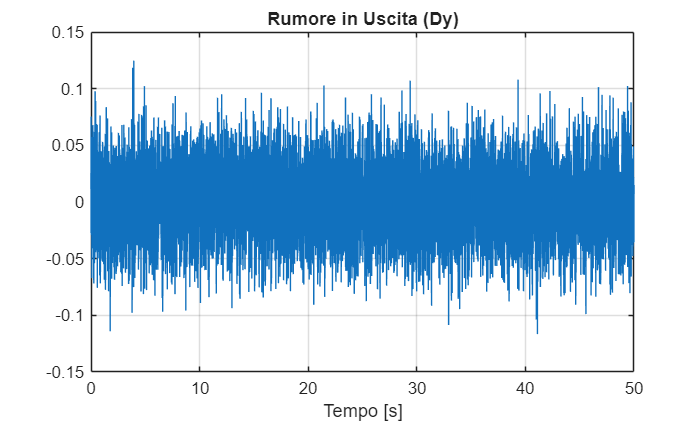

plot(out3.Dy.time, out3.Dy.signals.values)
title("Rumore in Uscita (Dy)");
xlabel("Tempo [s]");
grid;

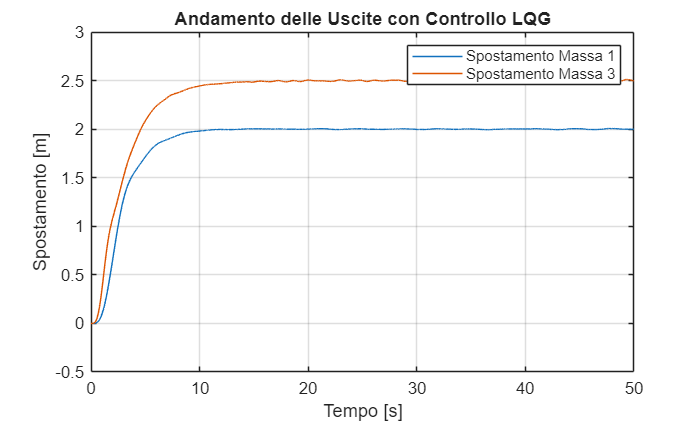

plot(out3.outputLQG_KAL.time, out3.outputLQG_KAL.signals.values)
title("Andamento delle Uscite con Controllo LQG");
xlabel("Tempo [s]");
ylabel("Spostamento [m]");
legend("Spostamento Massa 1","Spostamento Massa 3");
grid;

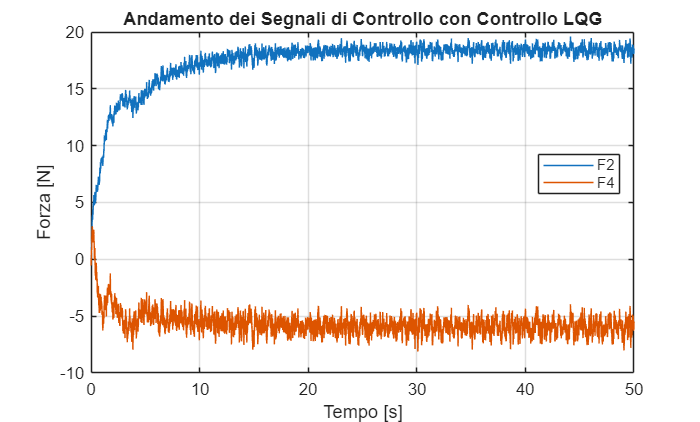

plot(out3.controlLQG_KAL.time, out3.controlLQG_KAL.signals.values)
title("Andamento dei Segnali di Controllo con Controllo LQG");
xlabel("Tempo [s]");
ylabel("Forza [N]");
legend("F2","F4",'Location','best');
grid;

### Schema Simulink

out4 = sim("Controllo_Ottimo_LQ_Disturbi.slx")

out4 =   Simulink.SimulationOutput:

        controlLQ_NOISE: [1x1 struct] 
         outputLQ_NOISE: [1x1 struct] 
       outputLQ_NOISE_N: [1x1 struct] 
                   tout: [10006x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Risultati con osservatore 

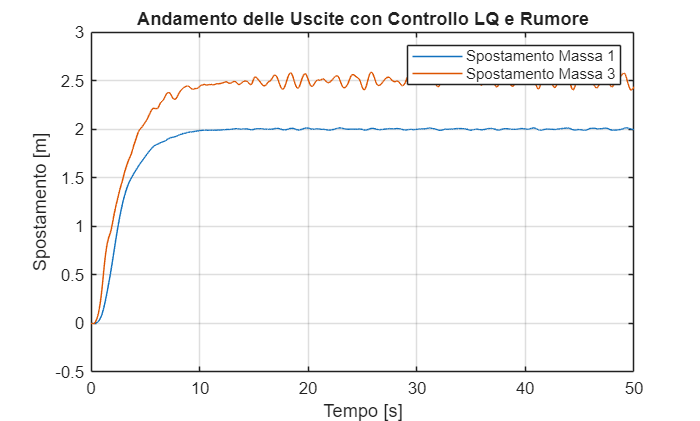

plot(out4.outputLQ_NOISE.time, out4.outputLQ_NOISE.signals.values)
title("Andamento delle Uscite con Controllo LQ e Rumore");
xlabel("Tempo [s]");
ylabel("Spostamento [m]");
legend("Spostamento Massa 1","Spostamento Massa 3");
grid;

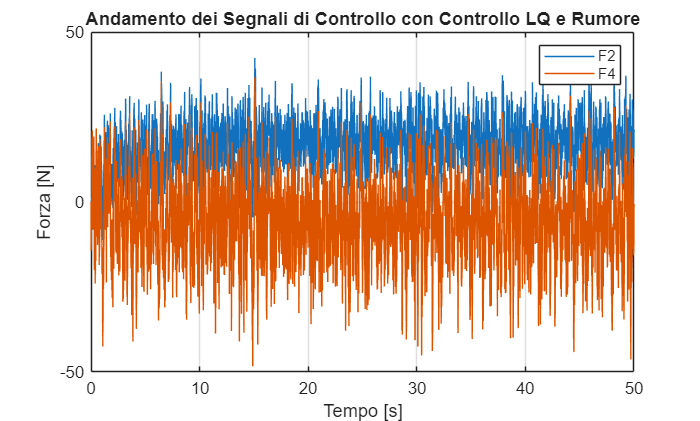

plot(out4.controlLQ_NOISE.time, out4.controlLQ_NOISE.signals.values)
title("Andamento dei Segnali di Controllo con Controllo LQ e Rumore");
xlabel("Tempo [s]");
ylabel("Forza [N]");
legend("F2","F4");
grid;

## Mixed Sensitivity Design (CONTROLLO $H_{\infty }$)

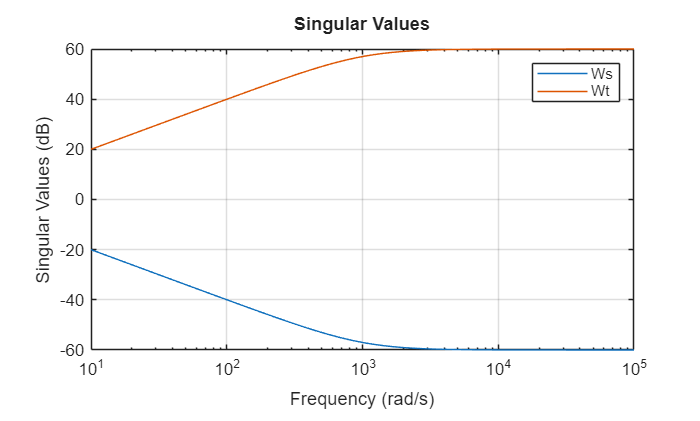

G=zpk(minreal(tf(sys),1e-5)); 
Ws=zpk(makeweight(1000,[1 1],1/1000)*eye(2));
Wt=zpk(makeweight(1/1000,[1 1],1000)*eye(2));
%Wt=[];
Wk=25*eye(2);
sigma(Ws,Wt)
legend("Ws","Wt");
grid;

Ws


Ws =
 
  From input 1 to output...
       0.001 (s+1000)
   1:  --------------
         (s+0.001)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.001 (s+1000)
   2:  --------------
         (s+0.001)
 
Continuous-time zero/pole/gain model.


Wt


Wt =
 
  From input 1 to output...
       1000 (s+0.001)
   1:  --------------
          (s+1000)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       1000 (s+0.001)
   2:  --------------
          (s+1000)
 
Continuous-time zero/pole/gain model.


Wk

Wk =     25     0
     0    25


[R,CL,gamma] = mixsyn(G,Ws,Wt,Wk);
%Ar=K.A; 
%Br=K.B; 
%Cr=K.C; 
%Dr=K.D; 
[Ar,Br,Cr,Dr] = ssdata(R);

L = sys*R;
I = eye(2);
S = minreal(inv(I+L));

18 states removed.


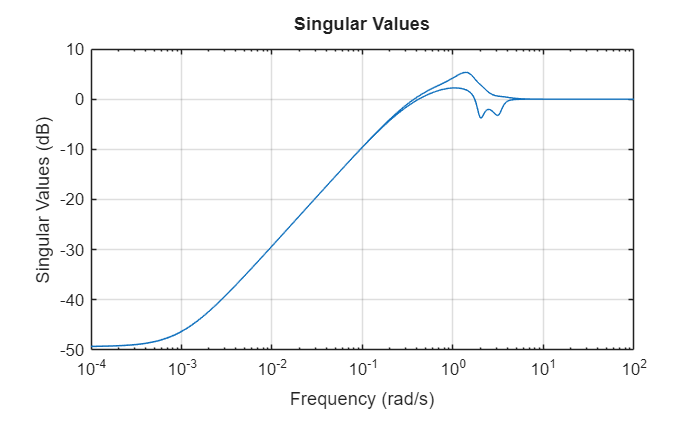

sigma(S), grid

T=minreal(L*S);

28 states removed.


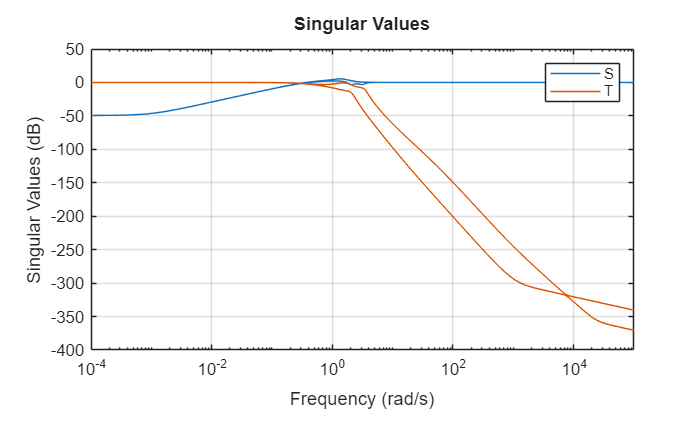

sigma(S,T)
legend("S","T");
grid;

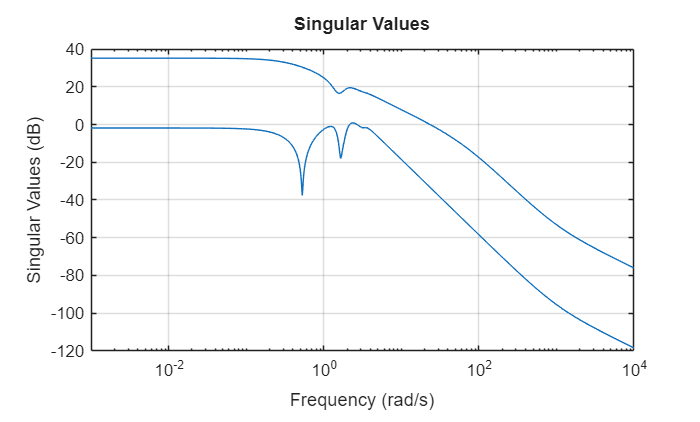

sigma(R*S,{1e-3,1e4})
grid

### Schema Simulink

out5 = sim("Controllo_H_Infinito.slx")

out5 =   Simulink.SimulationOutput:

               controlH: [1x1 struct] 
                outputH: [1x1 struct] 
                   tout: [10005x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Risultati:

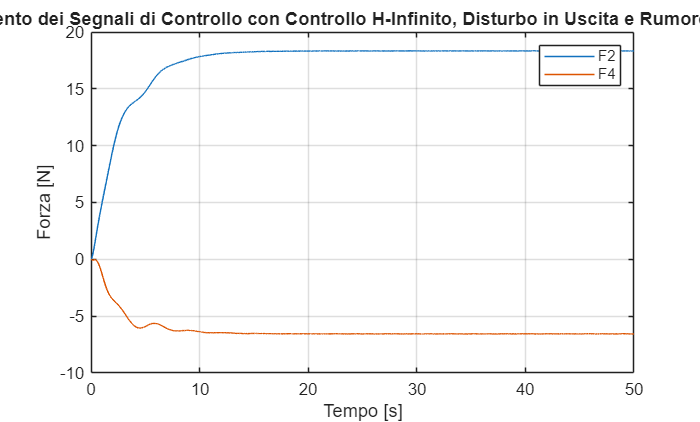

plot(out5.controlH.time, out5.controlH.signals.values)
title("Andamento dei Segnali di Controllo con Controllo H-Infinito, Disturbo in Uscita e Rumore di Misura");
xlabel("Tempo [s]");
ylabel("Forza [N]");
legend("F2","F4");
grid;

%plot(out.out5.time, out.out5.signals.values)
%title("Andamento delle uscite con controllo H-infinito");
%xlabel("time [s]");
%ylabel("shift [m]");
%legend("spostamento carrello 1","spostamento carrello 5",'Location','best');
%grid;

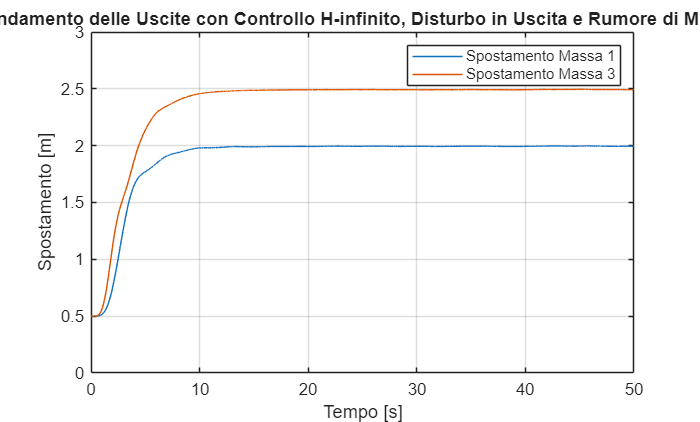

plot(out5.outputH.time, out5.outputH.signals.values)
title("Andamento delle Uscite con Controllo H-infinito, Disturbo in Uscita e Rumore di Misura");
xlabel("Tempo [s]");
ylabel("Spostamento [m]");
legend("Spostamento Massa 1","Spostamento Massa 3");
grid;

xlim([0.0 50.0])
ylim([0.0 3.0 ])